clc
clear all
g=9.81;
R=g/9;
thetad0=0;
theta0=1;
gamma=0.5;
[t,w]=pendulum3(R,theta0,thetad0,gamma);
ind1= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period1= 2*mean(diff(t(ind1(1:length(ind1)-1))));
omega1=2*pi/period1

omega1 = 2.9710

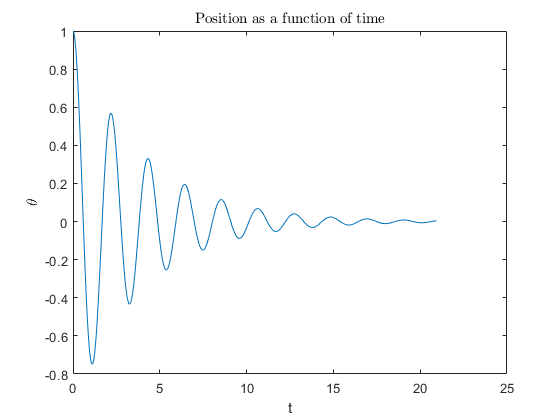

plot(t,w(:,1))
xlabel('t')
ylabel('\theta')
title('Position as a function of time','interpreter','latex')

(a) Damped oscillations

[t1,w1]=pendulum2(R,theta0,thetad0);
ind2= find(w1(:,2).*circshift(w1(:,2), [-1 0]) <= 0);
period2= 2*mean(diff(t1(ind2(1:length(ind2)-1))));
omega2=2*pi/period2

omega2 = 2.8182

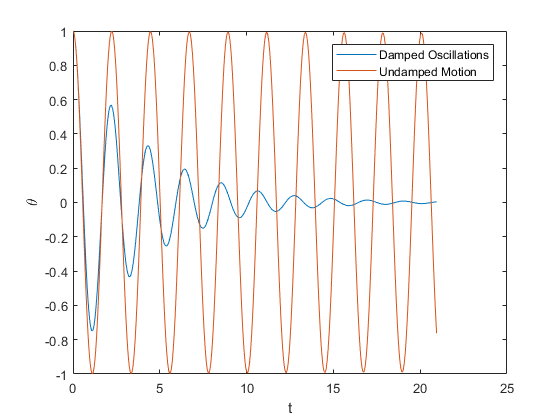

plot(t,w(:,1),t1,w1(:,1))
xlabel('t')
ylabel('\theta')
legend('Damped Oscillations','Undamped Motion')

(b) T_damped = 2.1148 s; T_undamped = 2.2295s; omega_damped = 2.9710 rad/s; omega_undamped = 2.88182 rad/s

Period will be shorter in damped oscillations.  

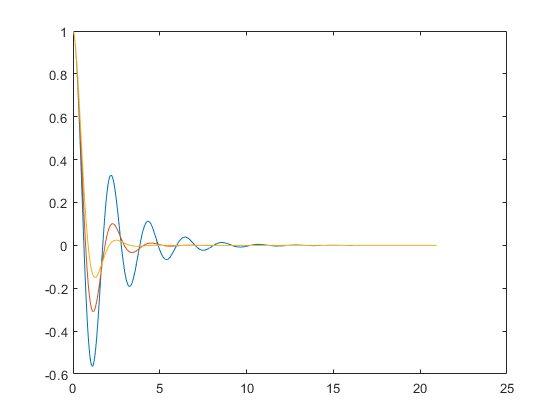

for gamma=1:3
    [t,w]=pendulum3(R,theta0,thetad0,gamma);
    ind= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
    period= 2*mean(diff(t(ind(1:length(ind)-1))));
    omega(gamma)=2*pi/period;
    plot(t,w(:,1))
    hold on
end
hold off

ind=zeros;

(b) omega1 = 2.9536; omega2 = 3.1118; omega3 = 3.2881; the frequency increase with greater damping.

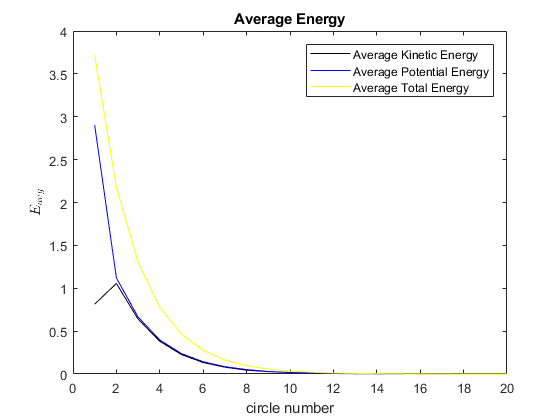

gamma=0.5;
[t,w]=pendulum3(R,theta0,thetad0,gamma);
K=0.5*R^2*w(:,2).^2;
V=0.5*9*R^2*(sin(w(:,1))).^2;
ind= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
for i=1:length(ind)-1
    for j=1:ind(i+1)-ind(i)
        K1(j)=K(ind(i)+j-1);
        V1(j)=V(ind(i)+j-1);
    end
    avgK(i)=mean(K1);
    avgV(i)=mean(V1);
    avgE(i)=avgK(i)+avgV(i);
    K1=zeros;
    V1=zeros;
    circle(i)=i;
end
plot(circle,avgK,'k-',circle,avgV,'b-',circle,avgE,'y-')
legend('Average Kinetic Energy','Average Potential Energy','Average Total Energy')
xlabel('circle number')
ylabel('$E_{avg}$','interpreter','latex')
title('Average Energy')

(c) The decrease is not uniform 

t_terminal = 1.1176

t_terminal = 1.6760

t_terminal = 4.0385

t_terminal = 5.7562

t_terminal = 7.0741

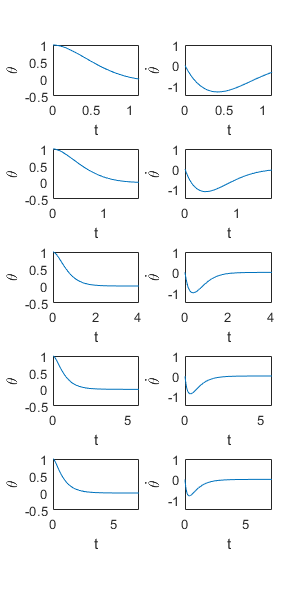

clc
for gamma=4:8
    [t,w,te]=pendulum32(R,theta0,thetad0,gamma);
    t_terminal=te
    subplot(5,2,2*gamma-7)
    plot(t,w(:,1))
    set(gcf,'Position',[0 0 200 600]);
    xlabel('t')
    ylabel('\theta')
    axis([0,te,-0.5,1])
    subplot(5,2,2*gamma-6)
    plot(t,w(:,2))
    set(gcf,'Position',[0 0 300 600]);
    xlabel('t')
    ylabel('$\dot{\theta}$','interpreter','latex')
    axis([0,te,-1.5,1])
end    

(d) for high value of gamma, the motion is not oscillatory (overdamping). The higher the damping, the faster the theta(t) decay to equilibrium. 

gamma=[0.5,2,4,6,8]

gamma =     0.5000    2.0000    4.0000    6.0000    8.0000


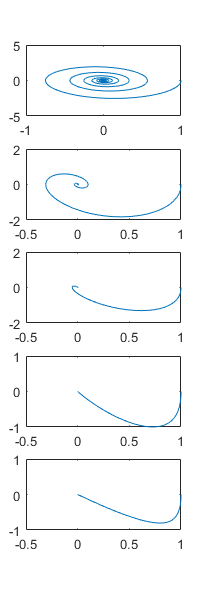

for i=1:length(gamma)
    [t,w]=pendulum3(R,theta0,thetad0,gamma(i));
    subplot(length(gamma),1,i)
    plot(w(:,1),w(:,2))
    set(gcf,'Position',[0 0 200 600]);
end     

The behavior of the path depend on gamma. With a small gamma, the pendulum is still able to oscillate. The path diagram would like like a swirl due to the small damping. With a high value of gamma, however, the pendulum would not be able to oscillate. Overdamping would occur in this case.